# 读取图像

img = imread('breast.png')

img = 235×213×3 uint8 数组
img(:,:,1) =

    13    21    35    32    20     6    14    42    25    26    37     8    11    34     6    14    53    22    29    19    31    15    13    20    10     9     5     8    10    10    14     3    11    15     9     5     3     4     7    13    43    14     7    19    17    18    10    26    12    22    12    27    13     3     2     6    15     7     1     1     2     2     3     3     5     1    10     7     5    18    11    23     3     5    10     8    25    26    14    12    18     3    11    53    14     9     6    11    16    15     5    13    10     2    11    30    18    23    23    24     3    17     7    12     5    10    10    29    25    39    13     4     1     4     5     1    11     9    18    10    11    21     8    19    11    14     2     7     8     1     6     0     6    13     3    24    20     5     9    13    12    25     7    12     9    38    28    25    11    28    48     9    21    46    31    83    11    23    11    25 

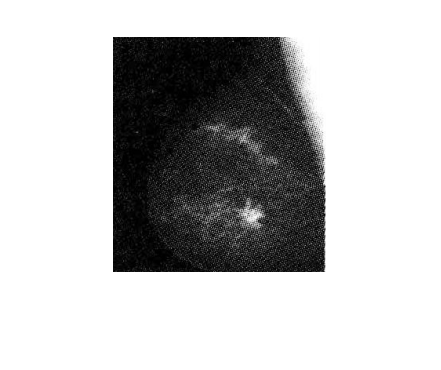

imshow(img)

# 图像反转

函数：imcomplement

img_inv = imcomplement(img)

img_inv = 235×213×3 uint8 数组
img_inv(:,:,1) =

   242   234   220   223   235   249   241   213   230   229   218   247   244   221   249   241   202   233   226   236   224   240   242   235   245   246   250   247   245   245   241   252   244   240   246   250   252   251   248   242   212   241   248   236   238   237   245   229   243   233   243   228   242   252   253   249   240   248   254   254   253   253   252   252   250   254   245   248   250   237   244   232   252   250   245   247   230   229   241   243   237   252   244   202   241   246   249   244   239   240   250   242   245   253   244   225   237   232   232   231   252   238   248   243   250   245   245   226   230   216   242   251   254   251   250   254   244   246   237   245   244   234   247   236   244   241   253   248   247   254   249   255   249   242   252   231   235   250   246   242   243   230   248   243   246   217   227   230   244   227   207   246   234   209   224   172   244   232   24

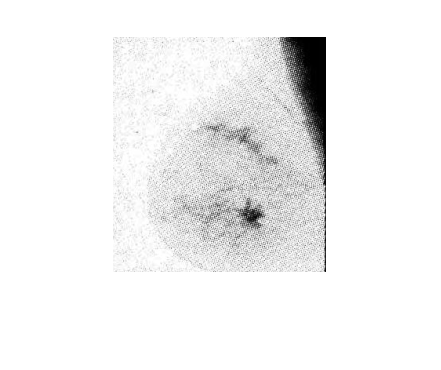

imshow(img_inv)

### 对比度拉伸

函数：imadjust（可能是直方图均衡？）

img1 = imadjust(img,[],[0,1]);
imshow(img1)

使用stretchlim自动选取应该重点关注的像素，限制输入的上下限。

img2 = imadjust(img,stretchlim(img),[0,1]);
imshow(img2)

# 对数变换

img = imread('light.png')

img = 480×492 uint8 矩阵
   255   249   238   238   251   255   255   245   244   248   252   253   252   253   255   255   255   254   246   241   240   244   251   255   255   255   247   240   239   243   249   254   255   255   247   240   240   245   254   255   252   252   251   250   249   248   247   247   248   248
   243   197   148   133   148   167   172   170   145   143   144   150   158   164   165   163   162   154   144   137   138   146   158   167   165   157   145   136   135   142   152   159   177   170   158   148   142   143   147   150   162   162   160   158   156   154   153   152   158   158
   249   159    62    20    24    34    35    33    13     5     2    12    30    40    36    28    29    20     9     1     4    16    32    42    63    54    42    33    33    41    52    61    55    50    41    33    30    31    35    38    42    40    38    35    32    30    28    26    28    28
   255   163    52    11    16    22    19    18    11     2     0     7  

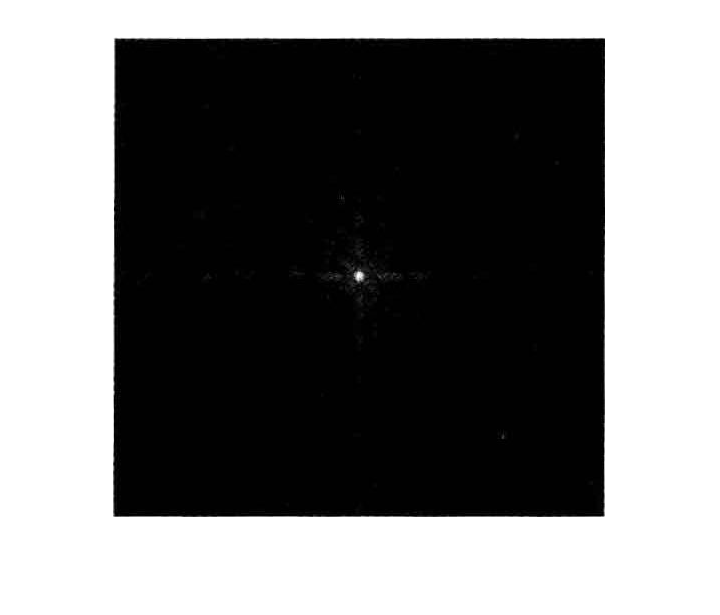

imshow(img)

函数定义

归一化函数：mat2gray

a = [1,2,3;
    4,5,6;
    7,8,9];
b = mat2gray(a)

b =          0    0.1250    0.2500
    0.3750    0.5000    0.6250
    0.7500    0.8750    1.0000


假设原图是Fourier频谱，为了在8比特系统上显示，需要将矩阵转化为uint8：im2uint8（要求single和double类输入在0到1范围内）

b = im2uint8(mat2gray(a))

b = 3×3 uint8 矩阵
     0    32    64
    96   128   159
   191   223   255


对数变换函数：

c = 2;
f = @(x)c.*log(1+double(x));

**应用：**

若直接映射到8比特系统上，最亮点支配了整张图的显示

img_without_log = im2uint8(img);
imshow(img_without_log)

进行对数变换：

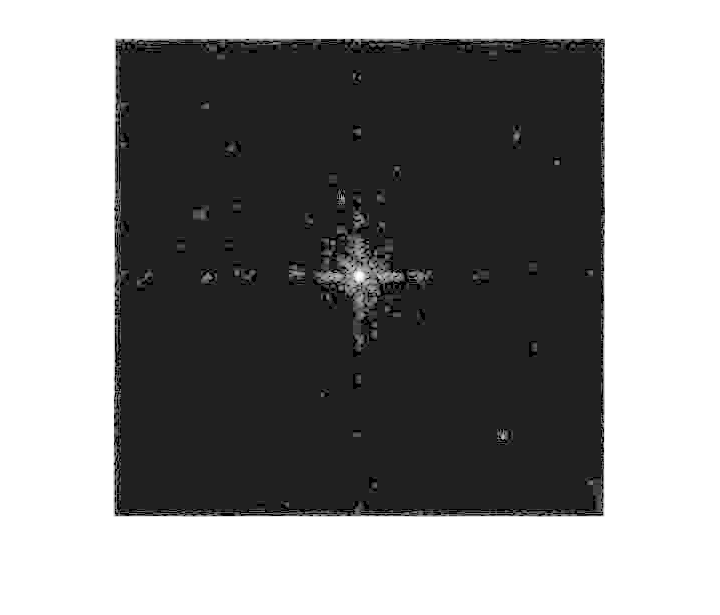

img_log = im2uint8(mat2gray(f(img)));
imshow(img_log)

# 利用内插函数interp1实现任意灰度变换

变量解释：

z：目标分布的自变量（不重要，只是interp1函数的一个必要输入值）

T：目标分布函数

f：输入图像

原理：利用内插，将 f 映射到 T (f)

img = rgb2gray(imread('lyf.jpg'))

img = 1772×1181 uint8 矩阵
   152   152   152   153   154   155   155   155   156   156   156   156   156   156   156   156   153   152   151   150   148   147   146   145   143   143   144   145   145   146   147   147   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   148   148
   151   152   152   153   154   154   155   155   155   155   155   155   155   155   155   155   153   152   151   150   148   147   146   145   143   143   144   145   145   146   147   147   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   147   148
   151   151   151   152   153   154   154   154   155   155   155   155   155   155   155   155   153   152   151   150   148   147   146   145   143   143   144   145   145   146   147   147   146   146   146   146   146   146   146   146   145   145   145   145   145   145   145   145   147   147
   150   150   151   151   152   153   153   154   154   154   154   154

subplot(1,2,1);
imshow(img)

以负变换为例：

T = [1;0]; %负变换
z = linspace(0,1,numel(T));
img_trans = im2uint8(interp1(z,T,double(mat2gray(img))))

img_trans = 1772×1181 uint8 矩阵
   103   103   103   102   101   100   100   100    99    99    99    99    99    99    99    99   102   103   104   105   107   108   109   110   112   112   111   110   110   109   108   108   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   107   107
   104   103   103   102   101   101   100   100   100   100   100   100   100   100   100   100   102   103   104   105   107   108   109   110   112   112   111   110   110   109   108   108   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   108   107
   104   104   104   103   102   101   101   101   100   100   100   100   100   100   100   100   102   103   104   105   107   108   109   110   112   112   111   110   110   109   108   108   109   109   109   109   109   109   109   109   110   110   110   110   110   110   110   110   108   108
   105   105   104   104   103   102   102   101   101   101   101

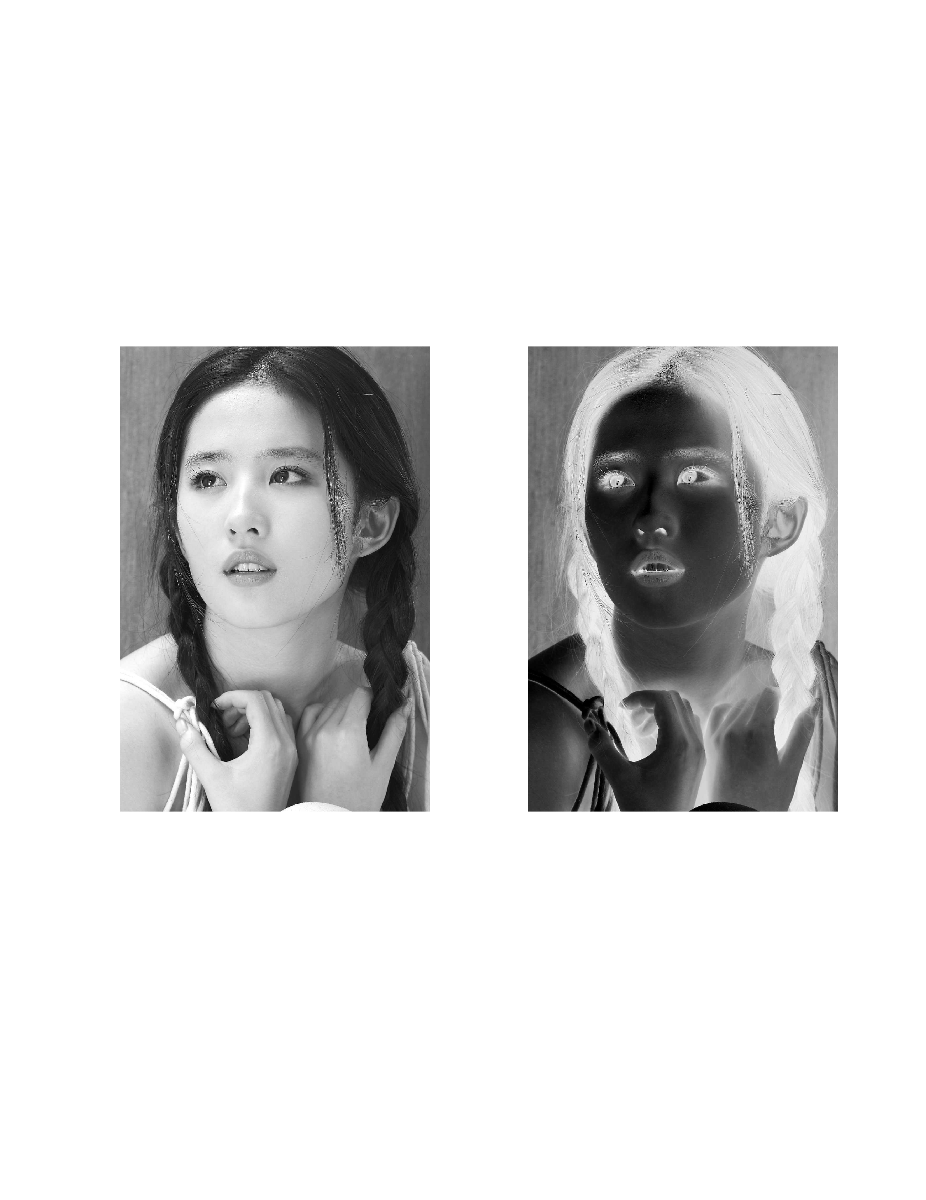

subplot(1,2,2)
imshow(img_trans)

# 综合函数

定义在末尾（matlab要求）

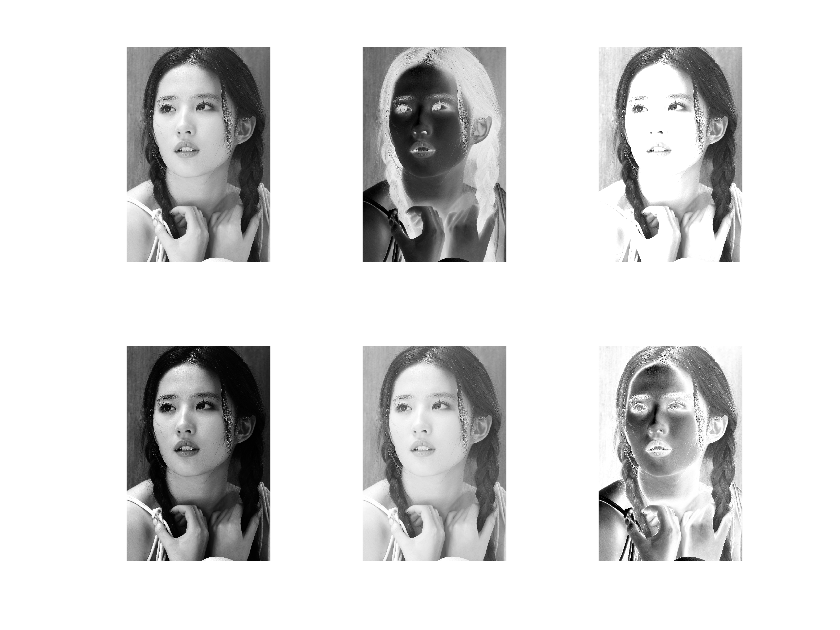

img1 = intrans(img,'neg');
img2 = intrans(img,'log',2,'uint8');
img3 = intrans(img,'gamma',2);
img4 = intrans(img,'gamma',0.6);
x=0:0.01:1;
img5 = intrans(img,'specified',sin(pi*x));
subplot(2,3,1); imshow(img);
subplot(2,3,2); imshow(img1)
subplot(2,3,3); imshow(img2)
subplot(2,3,4); imshow(img3)
subplot(2,3,5); imshow(img4)
subplot(2,3,6); imshow(img5)

综合函数定义

function g = intrans(f, method, varargin)
%INTRANS Performs intensity (gray-level) transformations.

%G = INTRANS(F,'neg') computes the negative of input image F.

%G = INTRANS(F，'log'，C，CLASS) computes C*log(1 + F) and
% multiplies the result by (positive) constant C.If the last two
% parameters are omitted, C defaults to 1, Because the log is usedfrequently to display Fourier spectra, 
% parameter CLASS offers the option to specify the class of the output as 'uint8' or
%'uint16'.If parameter CLASS is omitted, the output is of the same class as the input.

%G = INTRANS(F，'gamma'，GAM) performs a gamma transformation on the input image using parameter GAM (a required input).

%G = INTRANS(F，'stretch'，M，E) computes a contrast-stretching
%transformation using the expression 1./(1 + (M./F).^E).Parameter M must be in the range [0,1]. 
% The default value for M is mean2(tofloat(F)), and the default value for E is 4.

%G= INTRANS(F,specified，TXFUN) performs the intensitytransformation s = TXFUN(r) where r are input intensities,s are
% output intensities, and TXFUN is an intensity transformation(mapping) function, expressed as a vector with values in the
% range (0，1]. TXFUN must have at least two values.
%For the 'neg'，"gamma'，'stretch' and 'specified'transformations，floating-point input images whose values are outside the range (0，1] are scaled first using MAT2GRAY.Other
% images are converted to floating point using TOFLOAT. For the%log'transformation,floating-point images are transformeds without being scaled; other images are converted to floating point first using TOFLOAT
%The output is of the same class as the input, except if a% different class is specified for the 'log' option.
% Verify the correct number of inputs.
    error(nargchk(2,4,nargin))
    if strcmp(method,'log')
    % The log transform handles image classes differently than the
    % other transforms, so let the logTransform function handle that
    % and then return.
        g = logTransform(f, varargin{:});
        return;
    end
    
    
    %If f is floating point, check to see if it is in the range (0 1].
    % If it is not, force it to be using function mat2gray.
    if isfloat(f) && (max(f(:))>1 || min(f(:)) < 0) 
        f = mat2gray(f);
    end

    [f,revertclass] = tofloat(f);  % Store class of f for use later
    
    % Perform the intensity transformation specified.
    switch method
        case 'neg'
            g = imcomplement (f);
        case 'gamma'
            g = gammaTransform(f, varargin{:});
        case 'stretch'
            g = stretchTransform(f, varargin{:});
        case 'specified'
            g = specifiedTransform(f, varargin{:});
        otherwise
            error('Unknown enhancement method.')
    end
    
    %Convert to the class of the input image
    g = revertclass(g);
end

function g = gammaTransform(f, gamma)
    g = imadjust(f,[ ],[ ], gamma);
end

function g = stretchTransform(f, varargin)
    if isempty(varargin)
        % Use defaults .
        m = mean2(f);
        E = 4.0;
    elseif length(varargin) == 2
        m = varargin{l};
        E = varargin{2};
    else
        error('Incorrect number of inputs for the stretch method,')
    end
    g = 1./(1 + (m./f).^E);
end

function g = specifiedTransform(f, txfun)
    txfun = txfun(:); 
    % Force it to be a column vector.if any(txfun) > 1 Il any(txfun)<-0error('All elements of txfun must be in the range [0 1].)end
    T = txfun;
    x = linspace(0,1, numel(T));
    g = interp1(x, T, f);
end

function g = logTransform(f, varargin)
    [f, revertclass] = tofloat(f);
    if numel(varargin) >= 2
        if strcmp(varargin{2},'uint8')
            revertclass = @im2uint8;
        elseif strcmp(varargin{2},'uint16')
            revertclass = @im2uint16;
        else
            error('Unsupported CLASS option for ''log''method.')
        end
    
    end
    if numel(varargin) < 1 
        %Set default for C
        c = 1;
    else
        c = varargin{1};
    end

    g = c* (log(1 + f));
    g = revertclass(g);
% f is floating point with values in the range [0 1].
end

function[out, revertclass] = tofloat(in)
% TOFLOATConvert image to floating point
% [OUT，REVERTCLASS] = TOFLOAT(IN) converts the input image IN to
% floating-point.If IN is a double or single image, then OUT88equals IN，Otherwise，OUT equals IM2SINGLE(IN)，REVERTCLASS isa function handle that can be used to convert back to the classof IN.
    identity = @(x) x;
    tosingle = @im2single;
    
    table = {'uint8', tosingle, @im2uint8
            'uint16', tosingle, @im2uint16
            'int16', tosingle, @im2int16
            'logical', tosingle, @logical
            'double',identity, identity
            'single', identity, identity};
    
    classIndex = find(strcmp(class(in),table(:,1)));
    if isempty(classIndex)
        error('Unsupported input image class.');
    end
    out = table{classIndex,2}(in);
    revertclass = table{classIndex,3};
end